# Presentación Final (Cinemática Diferencial de Piernas)

Alan Iván Flores Juárez | A01736001

### Animación (matriz de transformación **homogénea global)**

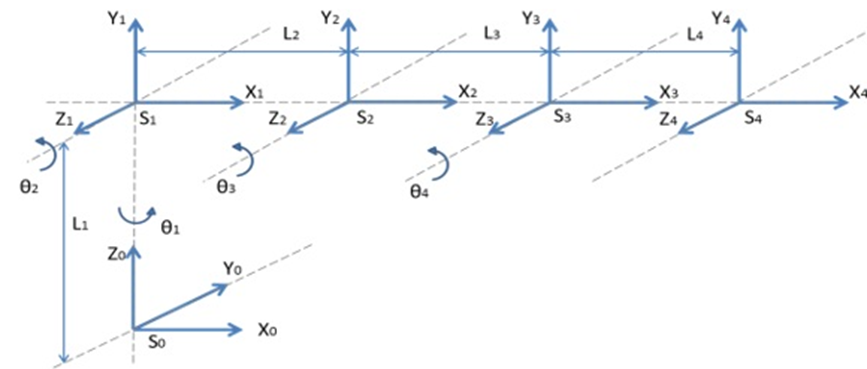

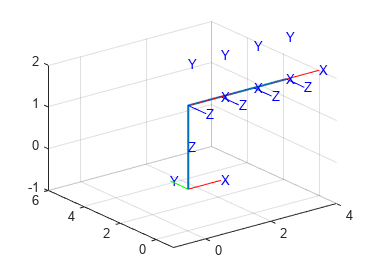

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%Rotx(90°) Tras(2)
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(rotz(0), [1 0 0]);
H3=SE3(rotz(0), [1 0 0]);
H4=SE3(rotz(0), [1 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;

%Coordenadas de la estructura de translación y rotación
x=[0 0 3 ];
y=[0 0 0 ];
z=[0 2 2 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
  %Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])

**Matriz de transformación homogénea global T**

disp(H40)

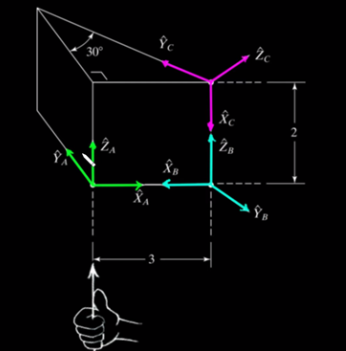

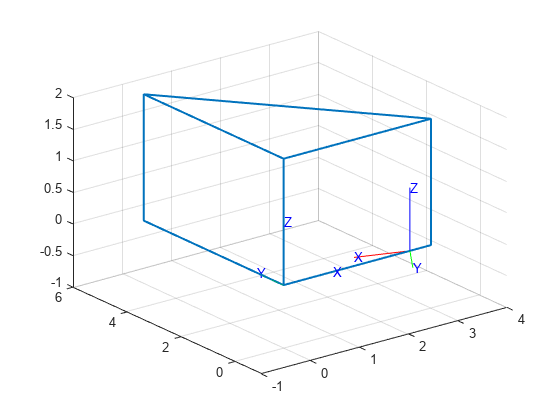

 %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;
%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])

% %Realizamos una animación para la siguiente trama
tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])

**Matriz de transformación homogénea global T**

disp(H30)

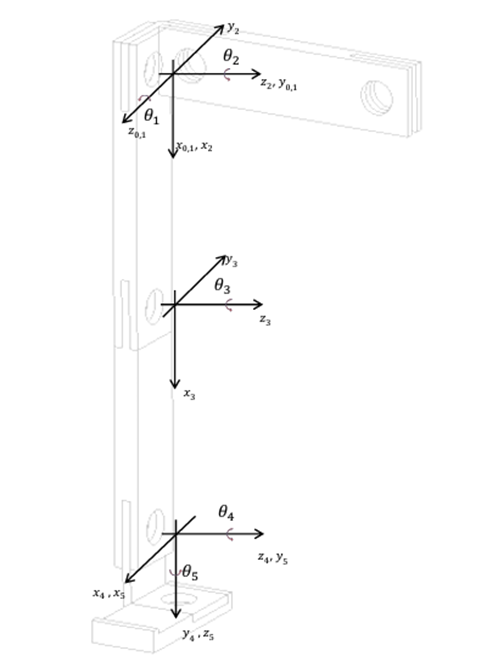

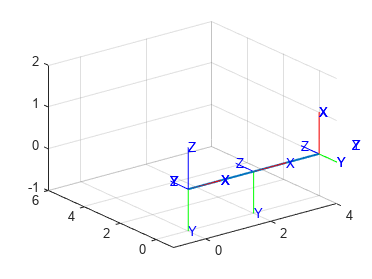

    -2.449e-16-2.449e-16         1         4
     2.449e-16        -1-2.449e-16-9.797e-16
             1 2.449e-16 2.449e-16 4.899e-16
             0         0         0         1


  %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%Rotx(90°) Tras(2)
H1=SE3(rotz(2*pi), [0 0 0]);
H2=SE3(rotx(-pi/2), [0 0 0]);
H3=SE3(rotz(2*pi), [2 0 0]);
H4=SE3(rotz(-pi/2), [2 0 0]);
H5=SE3(rotx(-pi/2), [0 0 0]);
H6=SE3(rotz(2*pi), [0 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;
H50= H40*H5;
H60= H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 2 4 ];
y=[0 0 0 ];
z=[0 0 0 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2]) 
% %Realizamos una animación para la siguiente trama
 tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])
 %Realizamos una animación para la siguiente trama
 tranimate(H40, H50,'rgb','axis', [-1 4 -1 6 -1 2])
 %Realizamos una animación para la siguiente trama
 tranimate(H50, H60,'rgb','axis', [-1 4 -1 6 -1 2])

**Matriz de transformación homogénea global T**

 disp(H60)

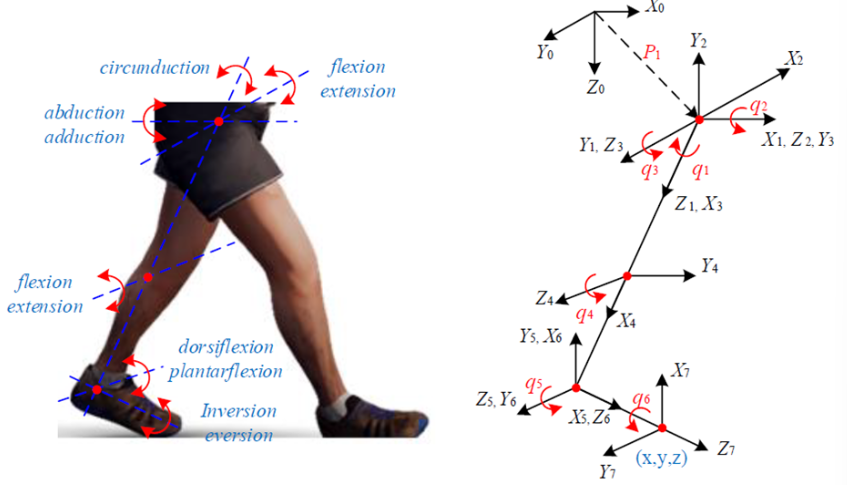

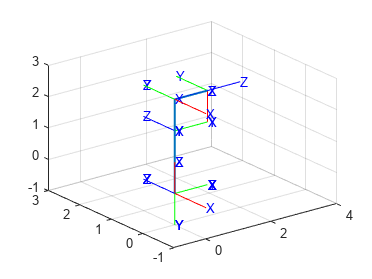

   %Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
%1-2
H1=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
%2-3
H3=SE3(roty(-pi/2), [0 0 0]);
H4=SE3(rotz(-pi/2), [0 0 0]);
%3-4
H5=SE3(rotz(0), [2 0 0]);
%4-5
H6=SE3(rotz(pi/2), [1 0 0]);
%5-6
H7=SE3(roty(pi/2), [0 0 0]);
H8=SE3(rotz(pi/2), [0 0 0]);
%6-7
H9=SE3(rotz(0), [0 0 1]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 
H40= H30*H4;
H50= H40*H5;
H60= H50*H6;
H70= H60*H7;
H80= H70*H8;
H90= H80*H9;

%Coordenadas de la estructura de translación y rotación
x=[0 0 0 1];
y=[0 0 0 0]; 
z=[0 2 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 3 -1 3]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 3 -1 3])
% 
% %Realizamos una animación para la siguiente trama
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 3 -1 3])
%Realizamos una animación para la siguiente trama
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 3 -1 3])
%Realizamos una animación para la siguiente trama
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 3 -1 3])
%Realizamos una animación para la siguiente trama
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 3 -1 3])
 %Realizamos una animación para la siguiente trama
 tranimate(H40, H50,'rgb','axis', [-1 4 -1 3 -1 3])
 %Realizamos una animación para la siguiente trama
 tranimate(H50, H60,'rgb','axis', [-1 4 -1 3 -1 3]) 
 %Realizamos una animación para la siguiente trama
 tranimate(H60, H70,'rgb','axis', [-1 4 -1 3 -1 3])
 %Realizamos una animación para la siguiente trama
 tranimate(H70, H80,'rgb','axis', [-1 4 -1 3 -1 3]) 
 %Realizamos una animación para la siguiente trama
 tranimate(H80, H90,'rgb','axis', [-1 4 -1 3 -1 3])

**Matriz de transformación homogénea global T**

 disp(H90)

     0         0         1         1
     0         1         0         0
    -1         0         0         3
     0         0         0         1


#### Modelo de **cinemática diferencial simbólica**

clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t l1 l2 l3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);

%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
%% Rotaciones

Rz1_1=[cos(th1) -sin(th1)   0;
       sin(th1)  cos(th1)   0;
       0        0           1];

Rz1_2=[cos(th2) -sin(th2)   0;
       sin(th2)  cos(th2)   0;
       0        0           1];

Rz1_3=[cos(th3) -sin(th3)   0;
       sin(th3)  cos(th3)   0;
       0        0           1];

Rz1_4=[cos(th4) -sin(th4)   0;
       sin(th4)  cos(th4)   0;
       0        0           1];

Rz1_5=[cos(th5) -sin(th5)   0;
       sin(th5)  cos(th5)   0;
       0        0           1];

Rz1_6=[cos(th6) -sin(th6)   0;
       sin(th6)  cos(th6)   0;
       0        0           1];

%% Articulaciones
P = sym(zeros(3, 1, 6));
R = sym(zeros(3, 3, 6));

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R1x = [1, 0, 0;
       0, 0, 1;
       0, -1, 0];

R1y = [0, 0, 1;
       0, 1, 0;
      -1, 0, 0];

R(:,:,1)=R1x*R1y*Rz1_1;

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0;0];
%Matriz de rotación de la junta 1 respecto a 0

R3y = [0, 0, -1;
       0, 1, 0;
       1, 0, 0];

R3z = [0, 1, 0;
       -1, 0, 0;
       0, 0, 1];

R(:,:,2)= R3y*R3z*Rz1_2;
%Articulación 3 
P(:,:,3)= [l1; 0;0];

R(:,:,3)=   Rz1_3;

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Articulación 4
P(:,:,4)= [l2; 0;0];

R(:,:,4)= Rz1_4;

%Articulación 5
P(:,:,5)= [0; 0;0];

R(:,:,5)= Rz1_5;

%Articulación 6
P(:,:,6)= [0; 0;l3];

R6y = [0, 0, 1;
       0, 1, 0;
       -1, 0, 0];

R6z = [0, -1, 0;
       1, 0, 0;
       0, 0, 1];

R(:,:,6)= R6y*R6z*Rz1_6;

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/       0,            0,      1, 0 \
|                                  |
| -cos(th1(t)),  sin(th1(t)), 0, 0 |
|                                  |
| -sin(th1(t)), -cos(th1(t)), 0, 0 |
|                                  |
\       0,            0,      0, 1 /



Matriz de Transformación global T2


/        sin(th2(t)),              cos(th2(t)),            0,      0 \
|                                                                    |
| -cos(th2(t)) sin(th1(t)),  sin(th1(t)) sin(th2(t)), cos(th1(t)), 0 |
|                                                                    |
|  cos(th1(t)) cos(th2(t)), -cos(th1(t)) sin(th2(t)), sin(th1(t)), 0 |
|                                                                    |
\             0,                        0,                 0,      1 /



Matriz de Transformación global T3


/        sin(#1),              cos(#1),            0,             l1 sin(th2(t))       \
|                                                                                      |
| -sin(th1(t)) cos(#1),  sin(th1(t)) sin(#1), cos(th1(t)), -l1 cos(th2(t)) sin(th1(t)) |
|                                                                                      |
|  cos(th1(t)) cos(#1), -cos(th1(t)) sin(#1), sin(th1(t)),  l1 cos(th1(t)) cos(th2(t)) |
|                                                                                      |
\           0,                    0,               0,                   1              /

where

   #1 == th2(t) + th3(t)




Matriz de Transformación global T4


/        sin(#1),              cos(#1),            0,      l1 sin(th2(t)) + l2 sin(#3) \
|                                                                                      |
| -sin(th1(t)) cos(#1),  sin(th1(t)) sin(#1), cos(th1(t)),       -sin(th1(t)) #2       |
|                                                                                      |
|  cos(th1(t)) cos(#1), -cos(th1(t)) sin(#1), sin(th1(t)),        cos(th1(t)) #2       |
|                                                                                      |
\           0,                    0,               0,                   1              /

where

   #1 == th2(t) + th3(t) + th4(t)

   #2 == l1 cos(th2(t)) + l2 cos(#3)

   #3 == th2(t) + th3(t)




Matriz de Transformación global T5


/        sin(#1),              cos(#1),            0,      l1 sin(th2(t)) + l2 sin(#3) \
|                                                                                      |
| -sin(th1(t)) cos(#1),  sin(th1(t)) sin(#1), cos(th1(t)),       -sin(th1(t)) #2       |
|                                                                                      |
|  cos(th1(t)) cos(#1), -cos(th1(t)) sin(#1), sin(th1(t)),        cos(th1(t)) #2       |
|                                                                                      |
\           0,                    0,               0,                   1              /

where

   #1 == th2(t) + th3(t) + th4(t) + th5(t)

   #2 == l1 cos(th2(t)) + l2 cos(#3)

   #3 == th2(t) + th3(t)




Matriz de Transformación global T6


/                    cos(th6(t)) cos(#1),                                       -sin(th6(t)) cos(#1),                          sin(#1),         l1 sin(th2(t)) + l2 sin(#3)   \
|                                                                                                                                                                             |
| cos(th1(t)) sin(th6(t)) + cos(th6(t)) sin(th1(t)) sin(#1), cos(th1(t)) cos(th6(t)) - sin(th1(t)) sin(th6(t)) sin(#1), -sin(th1(t)) cos(#1), l3 cos(th1(t)) - sin(th1(t)) #2 |
|                                                                                                                                                                             |
| sin(th1(t)) sin(th6(t)) - cos(th1(t)) cos(th6(t)) sin(#1), cos(th6(t)) sin(th1(t)) + cos(th1(t)) sin(th6(t)) sin(#1),  cos(th1(t)) cos(#1), l3 sin(th1(t)) + cos(th1(t)) #2 |
|                                                                                                                       






%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ #3 - #1,                 0,                        #4,              l2 cos(#5),       0, 0 \
|                                                                                            |
|    #2,   - l3 sin(th1(t)) - cos(th1(t)) #4,  sin(th1(t)) #2,  l2 sin(th1(t)) sin(#5), 0, 0 |
|                                                                                            |
\    0,                 #1 - #3,              -cos(th1(t)) #2, -l2 cos(th1(t)) sin(#5), 0, 0 /

where

   #1 == l3 cos(th1(t))

   #2 == l1 sin(th2(t)) + l2 sin(#5)

   #3 == sin(th1(t)) #4

   #4 == l1 cos(th2(t)) + l2 cos(#5)

   #5 == th2(t) + th3(t)




disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 1,      0,           0,           0,           0      \
|                                                          |
| 0, 0, cos(th1(t)), cos(th1(t)), cos(th1(t)), cos(th1(t)) |
|                                                          |
\ 1, 0, sin(th1(t)), sin(th1(t)), sin(th1(t)), sin(th1(t)) /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/                                 #2 #7 - #4 #6 + l2 #1 cos(#8)                                \
|                                                                                              |
| #4 #5 - #3 (l3 sin(th1(t)) + cos(th1(t)) #7) + #2 sin(th1(t)) #5 + l2 #1 sin(th1(t)) sin(#8) |
|                                                                                              |
\                     #3 #6 - #2 cos(th1(t)) #5 - l2 #1 cos(th1(t)) sin(#8)                    /

where

         _________
          d
   #1 == -- th4(t)
         dt

         _________
          d
   #2 == -- th3(t)
         dt

         _________
          d
   #3 == -- th2(t)
         dt

         _________
          d
   #4 == -- th1(t)
         dt

   #5 == l1 sin(th2(t)) + l2 sin(#8)

   #6 == l3 cos(th1(t)) - sin(th1(t)) #7

   #7 == l1 cos(th2(t)) + l2 cos(#8)

   #8 == th2(t) + th3(t)




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/                                   _________                                   \
|                                    d                                          |
|                                   -- th2(t)                                   |
|                                   dt                                          |
|                                                                               |
|                        cos(th1(t)) (#4 + #3 + #2 + #1)                        |
|                                                                               |
| _________                                                                     |
|  d                                                                            |
| -- th1(t) + #4 sin(th1(t)) + #3 sin(th1(t)) + #2 sin(th1(t)) + #1 sin(th1(t)) |
\ dt                                                                            /

where

         _________
          d
   #1 == -- th6(t)
         dt

         _________
        